birdname = 'br177yw112';
syls = ['d'];
days = [62, 661,662, 73, 86, 88];

% set spectogram parameters
spect_params = struct();
spect_params.overlap_windowsize = [0.9 4];
spect_params.numWindows = 60;

% Initialize feature matrix
spects_all = [];
labels_all = [];
failedSyls ={};

for d= 1:length(days)
    day = days(d)
    % change to folder containing files
    [~, ~,~,directory,~] = raster_params(birdname,day);
    cd(directory)

    spect_day = [];
    labels_day = [];

    try
    [spect_day, labels_day] = getSpectMatrix(syls, spect_params);
    [spects_all] = [spects_all; spect_day];
    [labels_all] = [labels_all, labels_day];

    catch exception
        message = ['failed for: ' num2str(day) ' -syl ' syls];
        failedSyls = [failedSyls; message];
        disp(message)
    end

    cd ..

end

day = 62

day = 661

day = 662

day = 73

% which syllables to include? 
syls = ['d'];
% Import the necessary libraries
import matlab.io.*
import statistics.toolbox.*

%% compile spectrogram matrix of syllables
%  load sound vectors and syllable onset/offset times
soundfiles = dir('*_songbout*.not.mat'); files = struct2table(soundfiles);
for fn = 1:size(files,1)
    filename = char(files.name(fn));
    recname(fn,:) = filename(1:end-8);
    % isrec(fn,1) = length(filename) < 39 && length(filename) > 35;
end
recmat = string(recname);

% Initialize variables
org_fn = cell(length(recmat),1); % store names of each unique recording file looped through
songbout_fn = [];
songbout_ons = zeros(length(recmat),1);
songbout_offs = zeros(length(recmat),1);
songbout_ons_intan = zeros(length(recmat),1);
songbout_offs_intan = zeros(length(recmat),1);
ons_intan_all = [];
offs_intan_all = [];
labels_all = [];
spects_all = [];

%% extract songbout and syllable times from songbout files
for i = 1:length(recmat)
    % open songbout recording file
    filename =char(recmat(i));
    underscores = strfind(filename, '_');
    org_fn{i} = [filename(1:underscores(end)-1) '.mat']; %remove 'songbout*'
    load(filename,'song_onset', 'song_offset','t_board_adc','board_adc_data');

    % Store all songbout on/off times
    songbout_ons(i) = song_onset;
    songbout_offs(i) = song_offset;

    % Calculate intan timestamps of songbout on/off times
    songbout_ons_intan(i) = t_board_adc(1);
    songbout_offs_intan(i) = t_board_adc(end);
    
    % store sound vector
    rawsong = board_adc_data;
   

    fn_notmat = [recmat{i} '.not.mat'];
    if exist(fn_notmat)
        load(fn_notmat,"onsets","offsets","labels");
        ons_intan = [];
        offs_intan =[]; 
        select_idx = [];
        labels_select =[];
        
        % choose trials for only desired syllables
        select_idx = ismember(labels, syls);
        labels_select = labels(select_idx);
        onsets = onsets(select_idx);
        offsets = offsets(select_idx);

        % store all of the labels
        labels_all = [labels_all, labels_select];

        % convert syllable onsets/offsets to seconds
        onsets_s = onsets./1000;
        offsets_s = offsets./1000;

        % calculate and concatenate the intan timestamp of syl onset and offset times
        songbout_fn = [songbout_fn; repmat(string(filename),length(onsets_s),1)];
        ons_intan = onsets_s + t_board_adc(1);
        offs_intan = offsets_s + t_board_adc(1);
        ons_intan_all = [ons_intan_all; ons_intan];
        offs_intan_all = [offs_intan_all; offs_intan];

        % get sound vector for each desired syllable
        for x=1:length(labels_select)
            F1 = []; T=[]; P1=[]; 
            Fs = 30000; %sampling rate in Hz
            spect_params = [0.9 4]; %[percent_overlap window_size_in_milliseconds]

            on_id = find(abs((t_board_adc-ons_intan(x)))==min(abs(t_board_adc-ons_intan(x)))); %which time in RAWSONG is closest to syllable onset?
            off_id = find(abs((t_board_adc-offs_intan(x)))==min(abs(t_board_adc-offs_intan(x)))); %...to syllable offset?

            syl_wav = rawsong(on_id:off_id); %raw waveform for current syllable
            [S1,F1,T1,P1] = spect_from_waveform(syl_wav,Fs,0,spect_params); %get syllable spectrogram
            S{x,i} = S1;
            % cut the spectrograms to equal duration lengths
            S_cut = S1(:,end-60:end);
            % reshape multidim spec to 1 row for each trial            
            S_collapsed = reshape(S_cut,1,[]);
            Slog = log(1+abs(S_collapsed)); % use log-scale for visualization
            
            % concatenate all spect trials
            spects_all = [spects_all; Slog]; % use log-scale for visualization
        end
    end
end




## Compile the matrix for feeding to tsne

% Step 3: Prepare Data for t-SNE
featureMatrix = spects_all;

% can implement something here that indexes just the rows for desired
% labels

% optional: normalize data?

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', 3, 'Distance','euclidean','Algorithm','exact');
disp(loss)

    0.3813



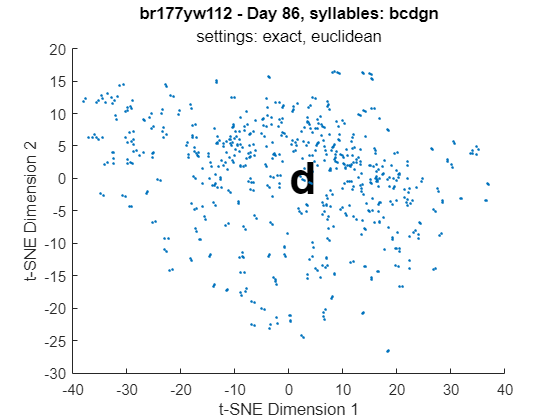

% Step 5: Assign unique colors based on labels
uniqueLabels = unique(labels_all);
numUniqueLabels = numel(uniqueLabels);
colors = lines(numUniqueLabels); % You can use any colormap you prefer

% Create a color map based on labels
labelColors = zeros(length(labels_all), 3);
for i = 1:numUniqueLabels
    labelColors(labels_all == uniqueLabels(i), :) = repmat(colors(i, :), [sum(labels_all == uniqueLabels(i)), 1]);
end

% Assuming your character labels are stored in a character array
charLabels = uniqueLabels; % Replace with your actual character labels

% Convert character labels to double
numericLabels = double(charLabels) - double('0') + 1;

% Create 3D scatter plot
figure;
hold on;
for i = 1:numUniqueLabels
    idx = labels_all == uniqueLabels(i);
    scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors(idx, :), 'filled');
    
    % Label each cluster with the associated character
    centroid = mean(tsneResult(idx, :), 1);
    text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold');
end
hold off;

title('br177yw112 - Day 86, syllables: bcdgn');
subtitle('settings: exact, euclidean')
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');

% Create 3D scatter plot
figure;
hold on;
for i = 1:numUniqueLabels
    idx = labels_all == uniqueLabels(i);
    scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 5, labelColors(idx, :), 'filled');
end
hold off;

title('br177yw112 - Day 68');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
zlabel('t-SNE Dimension 3');

% Assuming your original character labels are stored in a cell array
charLabels = double(uniqueLabels);
% Convert character labels to double
numericLabels = double(charLabels) - double('A') + 1;

% Create a separate plot for the color legend
legendPlot = axes('Position', [0.8, 0.1, 0.05, 0.8]); % Adjust position as needed
colormap(jet(numUniqueLabels)); % Use a colormap that matches the scatter plot
caxis([1, numUniqueLabels]);
colorbar(legendPlot, 'Ticks', 1:numUniqueLabels, 'TickLabels', arrayfun(@(x) char('A' + x - 1), 1:numUniqueLabels, 'UniformOutput', false));

% You can optionally remove the color legend from the scatter plot
% colorbar('off');
